# legge di ohm

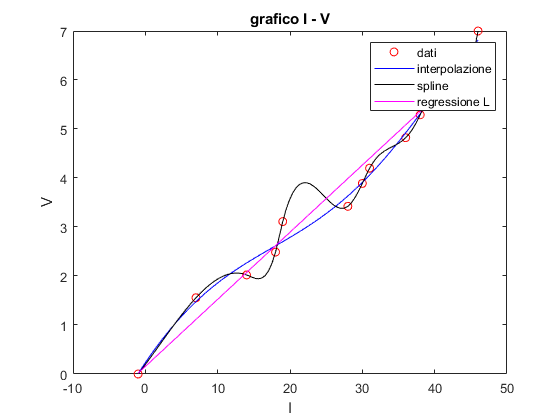

clear all
close all
load datiOhm.mat

plot(I,V,"or")
title("grafico I - V")
xlabel("I")
ylabel("V")

hold on
c = polyfit(I,V,5);
xp = linspace(I(1),I(end),100);
p = polyval(c,xp);
plot(xp,p,'-b')
p1 = interp1(I,V,xp,"spline");
plot(xp,p1,'-k')
c1 = polyfit(I,V,1);
p2 = polyval(c1,xp);
plot(xp,p2,'-m')
legend("dati","interpolazione",'spline','regressione L')


retta=polyval(c1,I);
scarto_quadratico=norm(V-retta)^2

scarto_quadratico = 1.2955

# DATI -> residui  eliminazione del valore anomalo

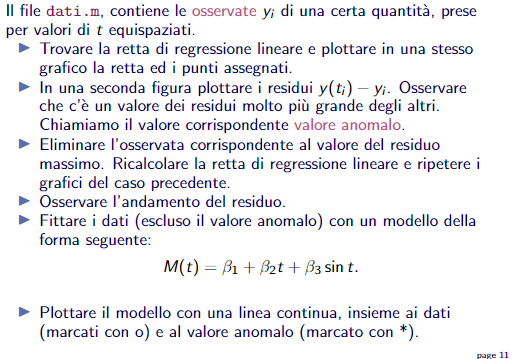

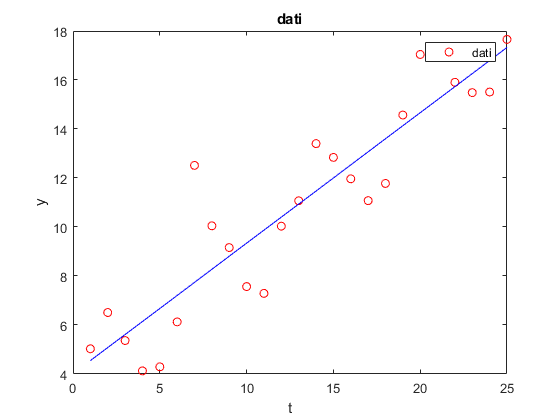

clear all
close all
dati
plot(t,y,'or')
hold on
title('dati')
xlabel('t')
ylabel('y')

c = polyfit(t,y,1);
xp = linspace(t(1),t(end),101);
p = polyval(c,xp);
plot(xp,p,'-b')
legend('dati')

hold off

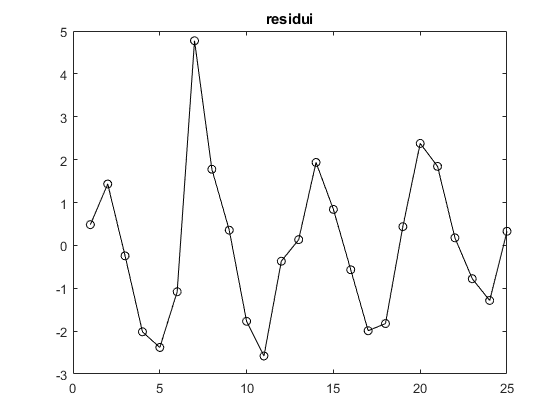

figure()
p1 = polyval(c,t);
res = y-p1;
plot(t,res,'-ok')
title('residui')

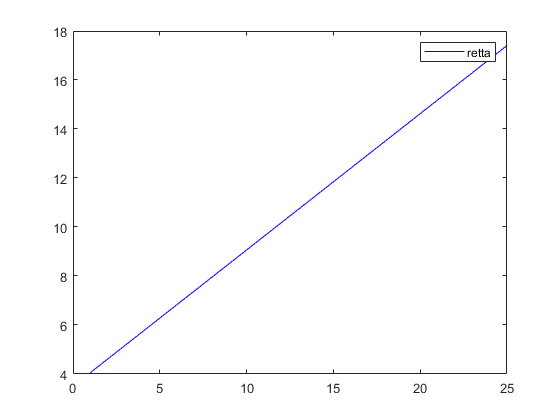


[anomalo,indice]=max(abs(res));
t(indice) = [];
y(indice) = [];
c = polyfit(t,y,1);
xp = linspace(t(1),t(end),101);
p = polyval(c,xp);
figure
plot(xp,p,'-b')
legend('retta')

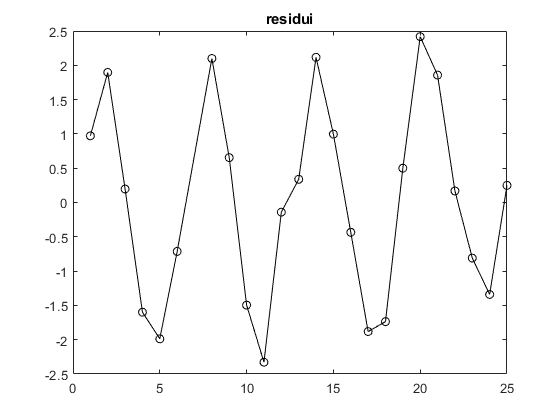


figure()
p1 = polyval(c,t);
res = y-p1;
plot(t,res,'-ok')
title('residui')

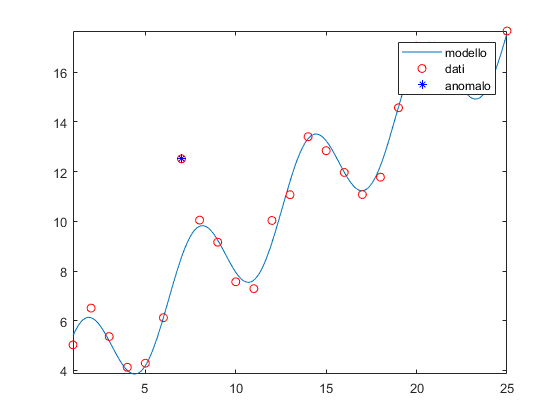


B = [ones(size(t)),t,sin(t)];
beta = B\y;
M = @(t) beta(1) + beta(2)*t + beta(3)*sin(t);
figure
fplot(M,[t(1) t(end)])
hold on
dati
plot(t,y,'or')
plot(t(indice),y(indice),'*b')
legend("modello","dati","anomalo")

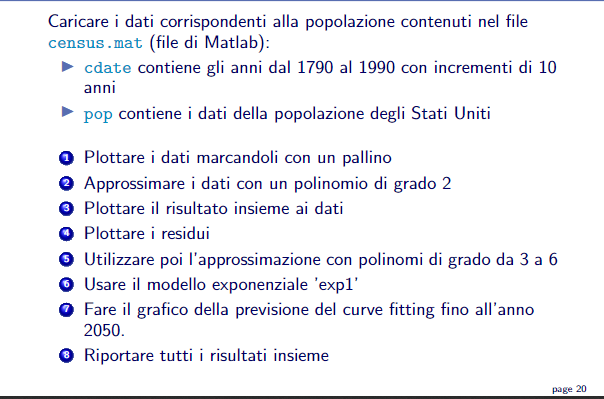

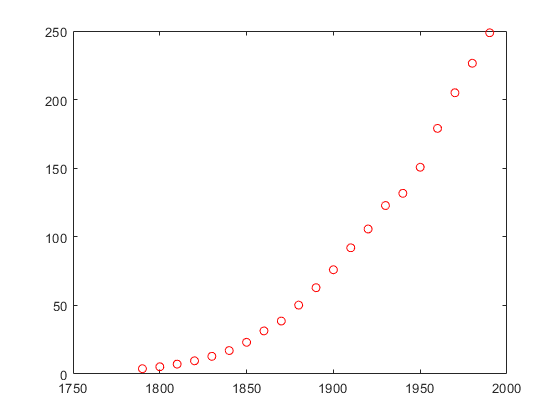

clear all
close all
load census
plot(cdate,pop,'or')

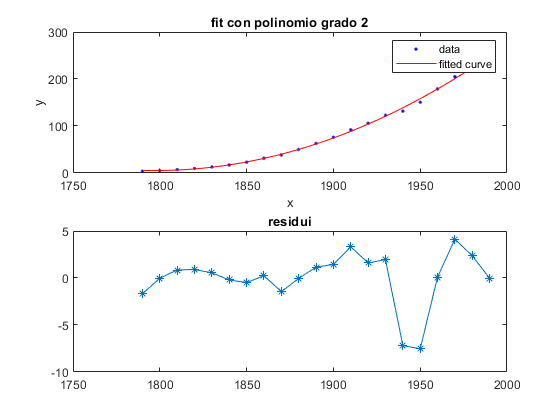

[pop2,gof2]=fit(cdate,pop,'poly2');
figure
subplot(2,1,1)
plot(pop2,cdate,pop)
title('fit con polinomio grado 2')
subplot(2,1,2)
plot(cdate,pop-pop2(cdate),'*-')
title("residui")


pop2=fit(cdate,pop,'poly2');
pop3=fit(cdate,pop,'poly3','Normalize','on');
pop4=fit(cdate,pop,'poly4','Normalize','on');
pop5=fit(cdate,pop,'poly5','Normalize','on');
pop6=fit(cdate,pop,'poly6','Normalize','on');
figure
plot(cdate,pop,'o')
hold on
plot(pop2,'r')
plot(pop3,'b')
plot(pop4,'g')
plot(pop5,'m')
plot(pop6,'b--')
legend('dati','pop2','pop3','pop4','pop5','pop6','Location','NorthWest')
popExp=fit(cdate,pop,'exp1')

popExp =      General model Exp1:
     popExp(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   4.851e-11  (-6.82e-11, 1.652e-10)
       b =     0.01474  (0.01351, 0.01597)

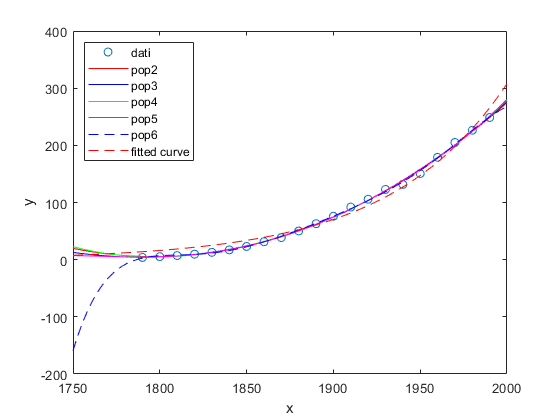

plot(popExp,'r--')

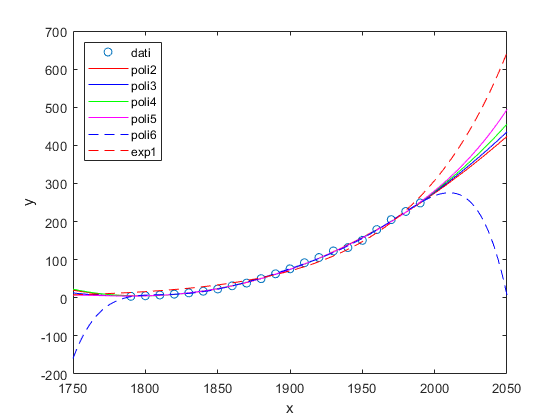


figure
plot(cdate,pop,'o')
xlim([1750 2050])
hold on
plot(pop2,'r')
plot(pop3,'b')
plot(pop4,'g')
plot(pop5,'m')
plot(pop6,'b--')
plot(popExp,'r--')
legend('dati','poli2','poli3','poli4','poli5','poli6','exp1','Location','NorthWest')

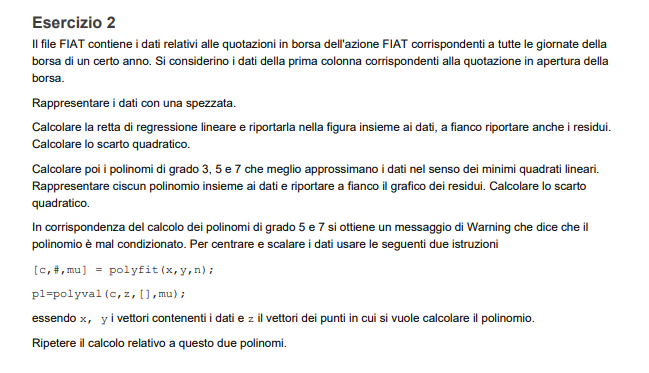

clear all
close all
load FIAT.mat
dati = fiat(:,1);
t = 1:1:252;

In corrispondenza del calcolo dei polinomi di grado 5 e 7 si ottiene un messaggio di Warning che dice che il polinomio è mal condizionato. 

Per centrare e scalare i dati usare le seguenti due istruzioni

 **[c,#,mu] = polyfit(x,y,n);**

** p1=polyval(c,z,[],mu); **

essendo x, y i vettori contenenti i dati e z il vettori dei punti in cui si vuole calcolare il polinomio.

si sostituisce al posto di **normalize,on**

polinomio di grado n = 1


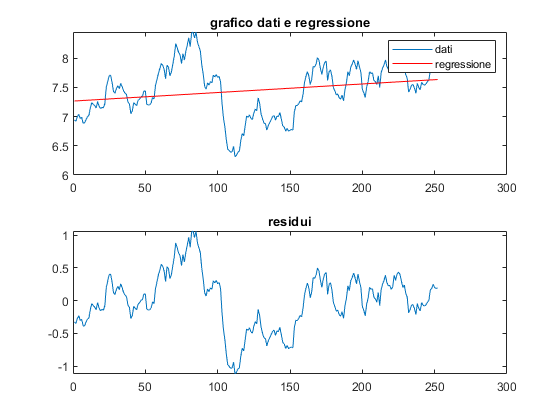

scarto quadratico


   46.9957


polinomio di grado n = 3


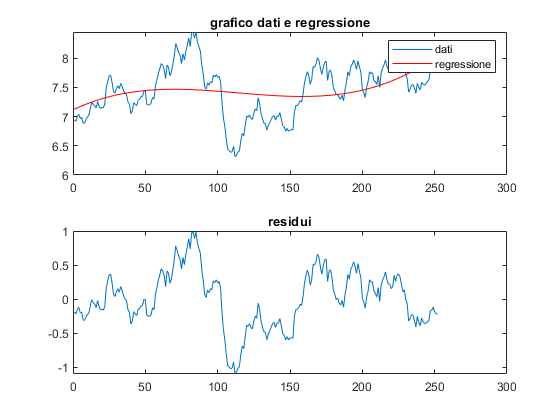

scarto quadratico


   43.0959


polinomio di grado n = 5


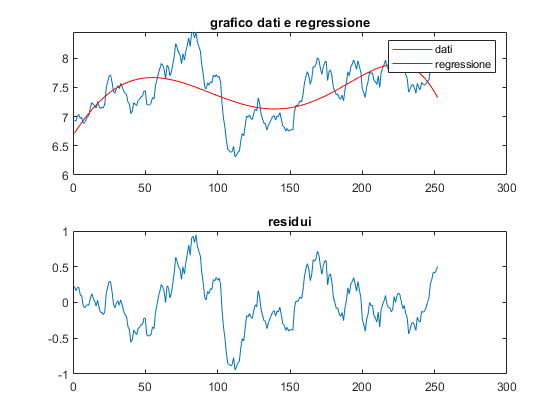

scarto quadratico


   32.6653


polinomio di grado n = 7


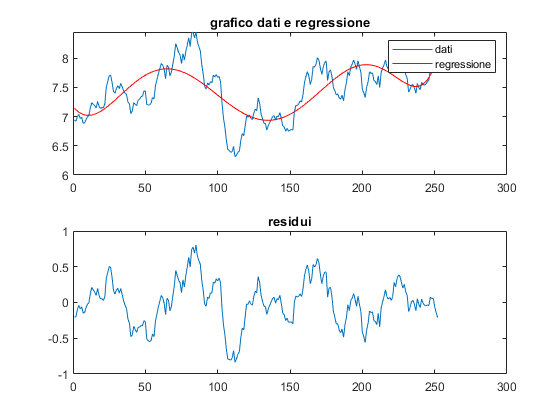

scarto quadratico


   24.8070


for i = 1:2:7
    disp("polinomio di grado n = " + i)
    figure()
    subplot(2,1,1)
    plot(dati)
    hold on 
    [fit_curve,gof]=fit(t',dati,"poly"+string(i),'Normalize','on');
    plot(t,fit_curve(t),'-r')   
    legend('dati','regressione')
    title('grafico dati e regressione')
    subplot(2,1,2)  
    plot(t,-fit_curve(t)+dati)
    title('residui')
    disp("scarto quadratico")
    disp(gof.sse)
end

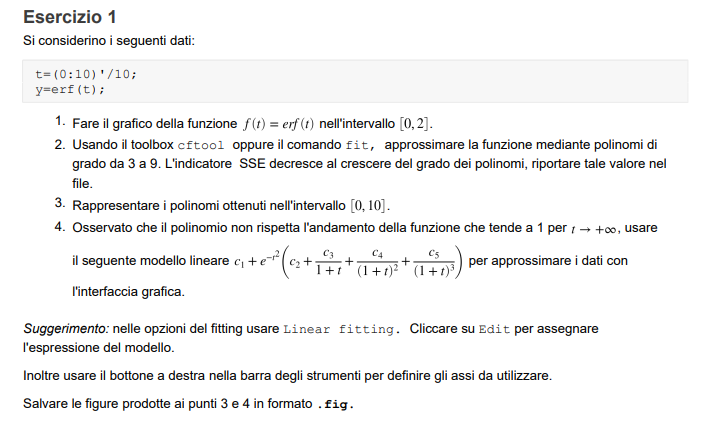

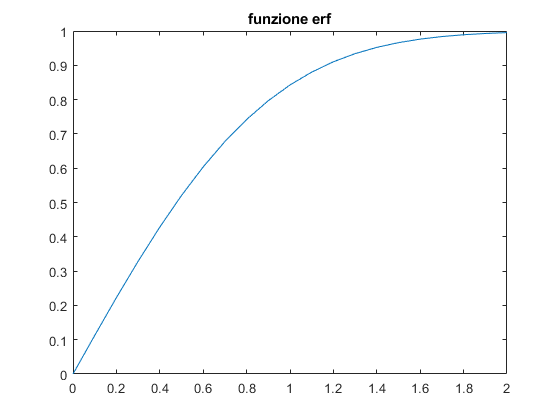

clear all
close all

t = (0:20)'/10;
t1 =(0:100)'/10;
y = erf(t);
plot(t,y);
title("funzione erf")

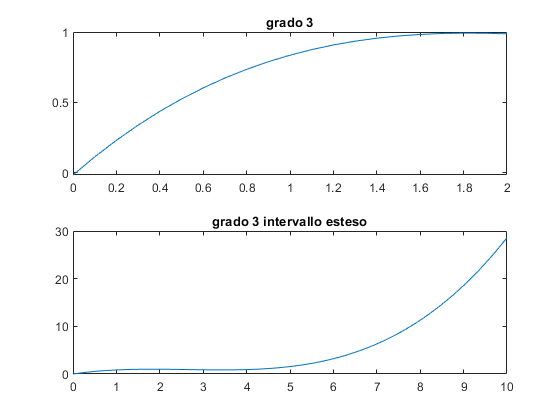

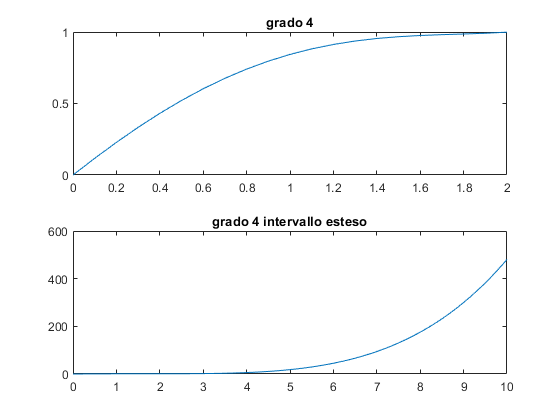

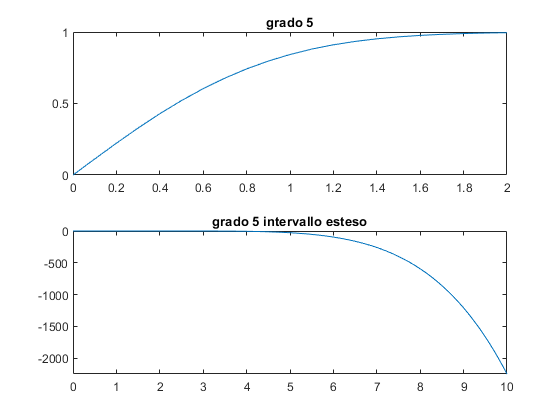

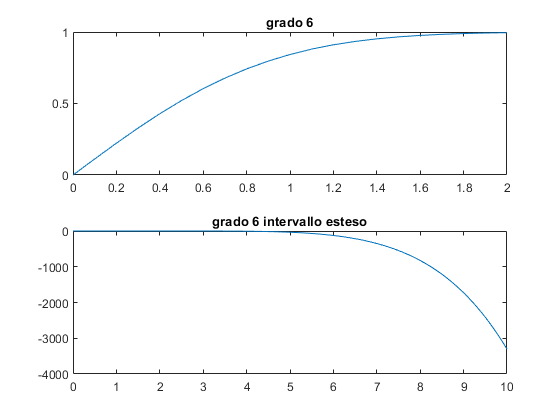

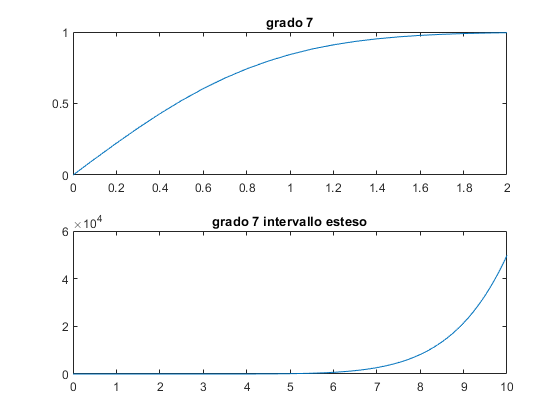

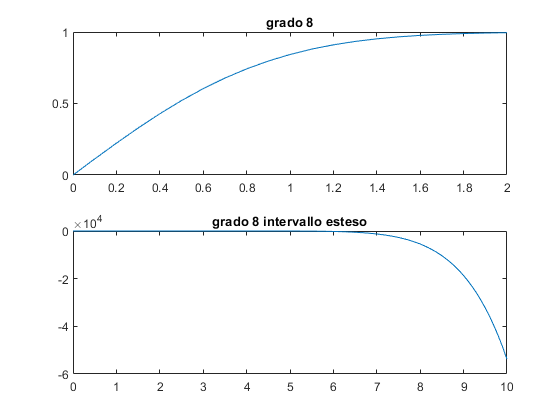

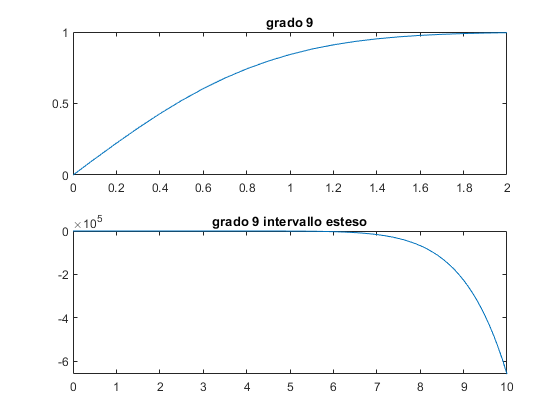

sse = zeros(7,1);
for n = 3:1:9
    [fit_curve,gof]=fit(t,y,"poly"+string(n),'Normalize','on');
    figure()
    subplot(2,1,1)
    plot(t,fit_curve(t))
    title("grado "+n)
    subplot(2,1,2)
    plot(t1,fit_curve(t1))
    title("grado "+n+" intervallo esteso")    
    sse(n-2) = gof.sse;
end

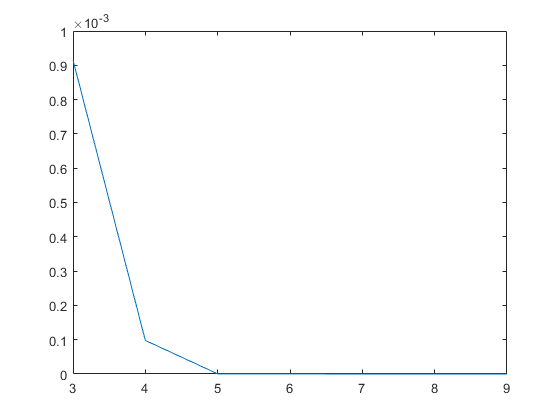

figure
plot(3:9,sse)

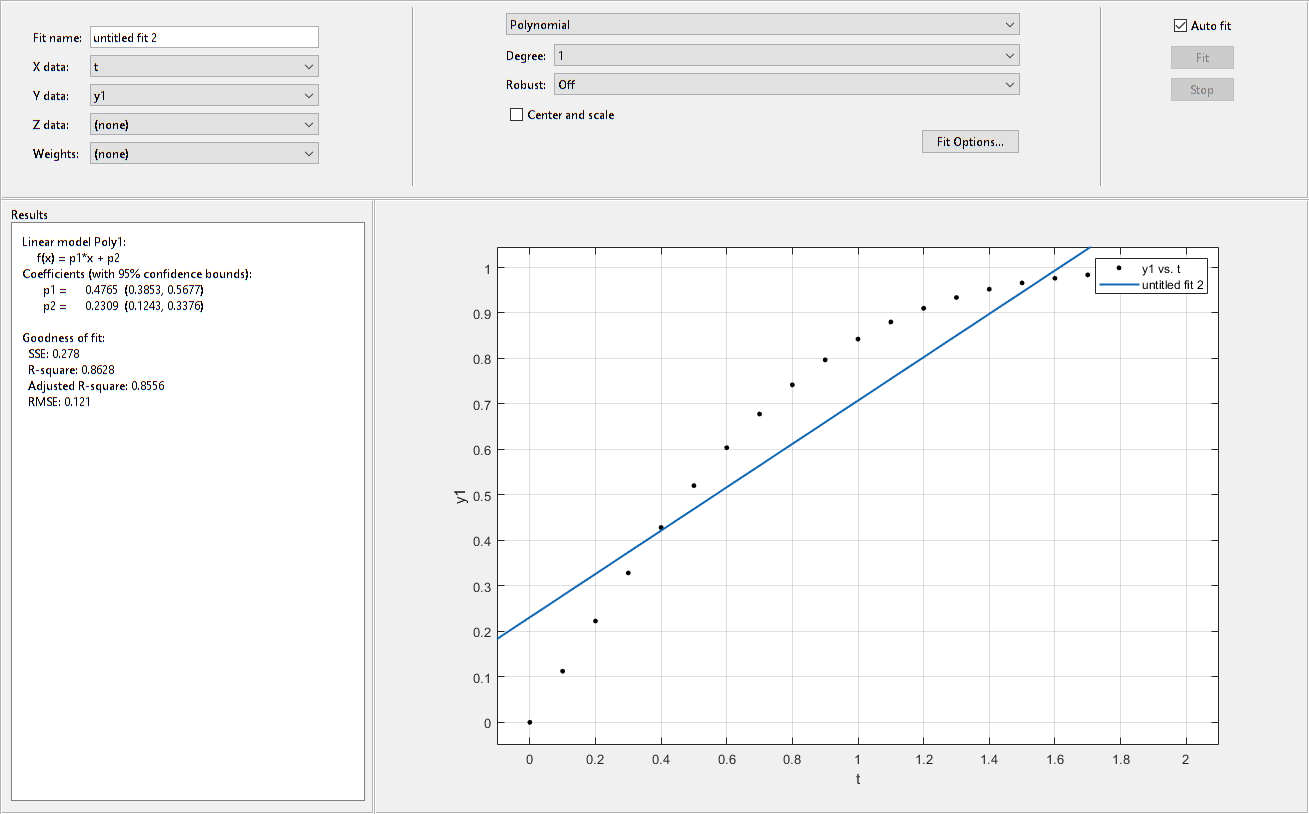

cftool(t,erf(t))


%% modello realizzato con matrice

%c=exp(-t.^2);
%B=[ones(size(t)),c,c./(1+t),c./((1+t).^2),c./((1+t).^3)];
%b=B\y
%x=(0:100)'/10;
%cost=exp(-x.^2);
%M=@(x) b(1)+cost.*(b(2)+b(3)./(1+x)+b(4)./((1+x).^2)+b(5)./((1+x).^3));
%figure
%plot(x,M(x))

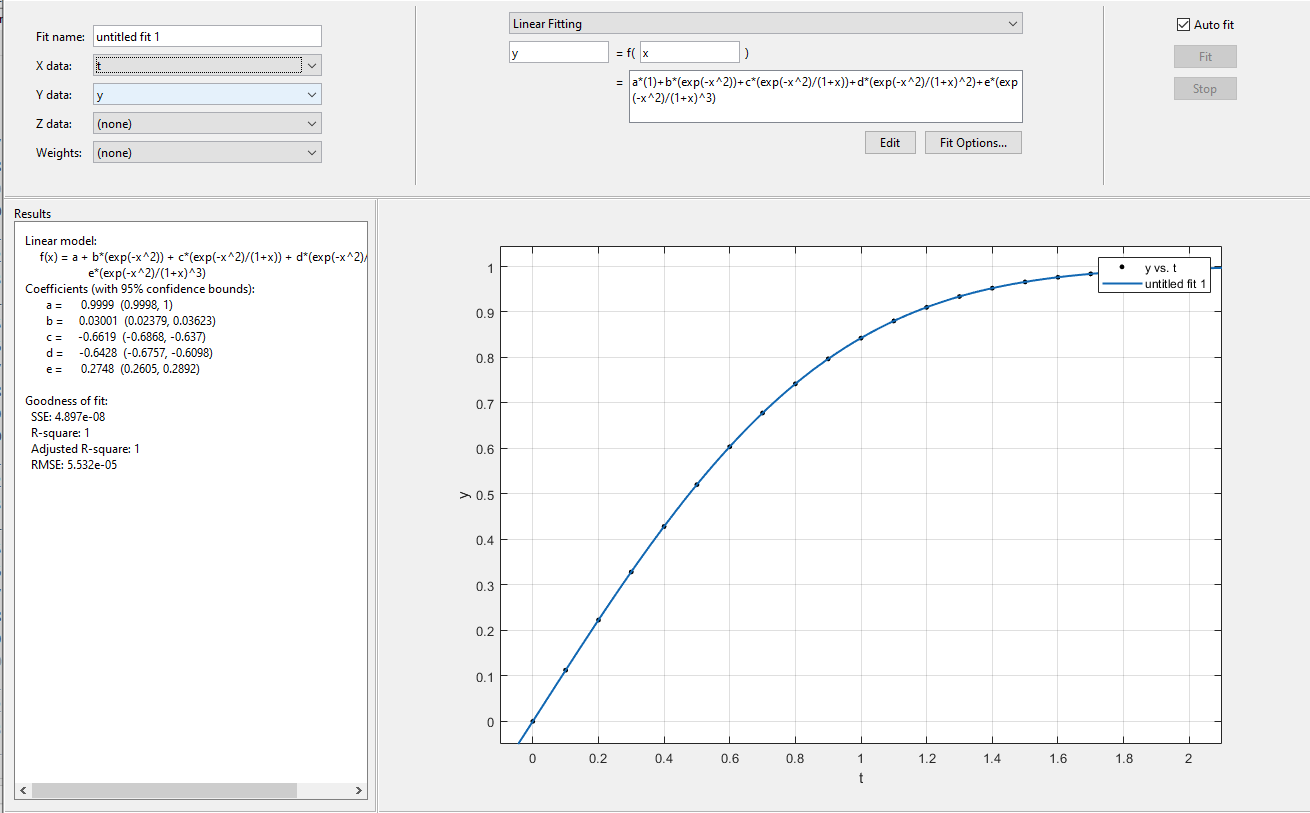

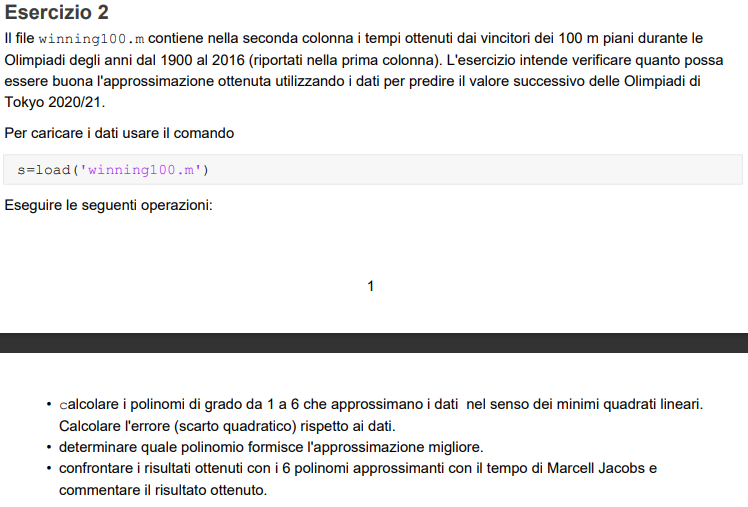

clear all
close all
s=load('winning100.m')

s = 	1.0e+03 *

    1.9000    0.0108
    1.9040    0.0110
    1.9080    0.0108
    1.9120    0.0108
    1.9200    0.0108
    1.9240    0.0106
    1.9280    0.0108
    1.9320    0.0103
    1.9360    0.0103
    1.9480    0.0103


tempo = zeros(1,6)

tempo =      0     0     0     0     0     0


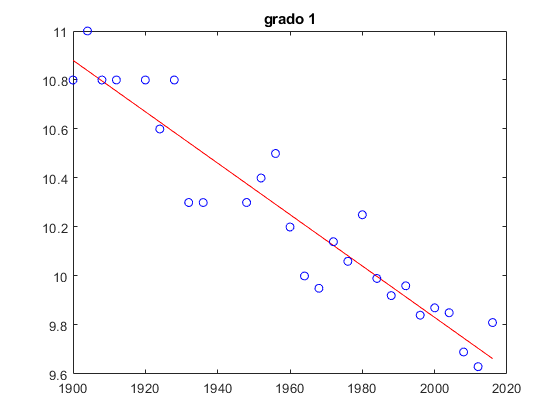

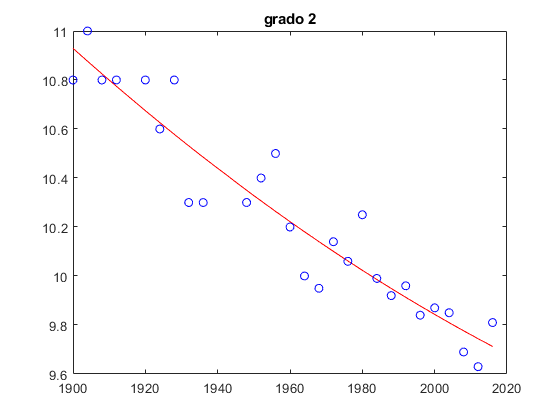

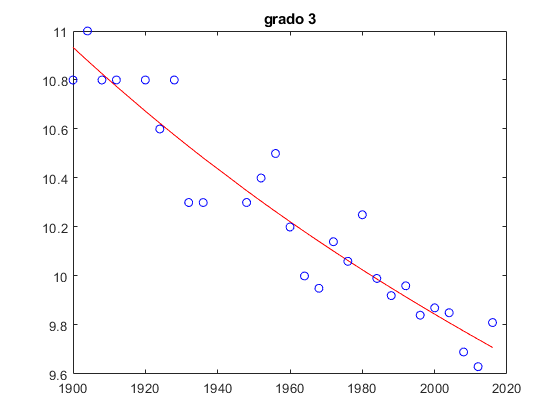

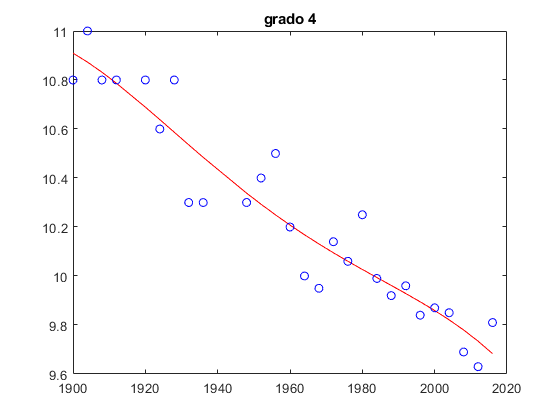

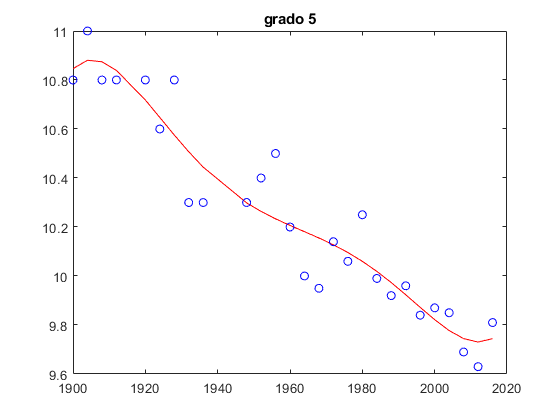

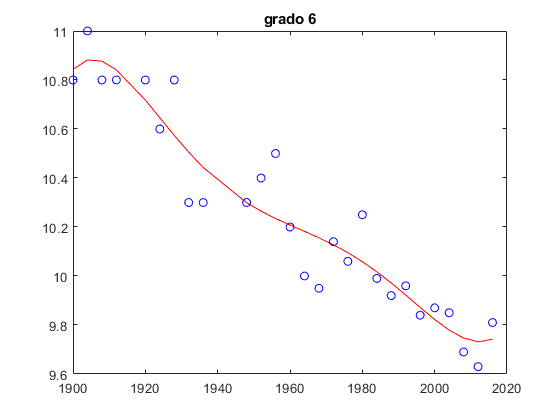

for n = 1:1:6
    [fit_curve,gof]=fit(s(:,1),s(:,2),"poly"+string(n),'Normalize','on');
    figure()
    plot(s(:,1),fit_curve(s(:,1)),'-r',s(:,1),s(:,2),'ob')
    title("grado "+n)
    tempo(n) = fit_curve(2020);
end

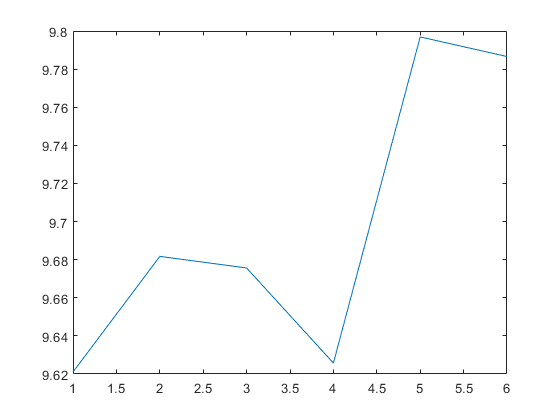

figure
plot(1:6,tempo)